# **HomeWork n.1 2023/24**

### *   Francesco Ferrillo 0124002921*

## **Punto 1: **

#### Definite la function Matlab che implementa la vostra funzione di riferimento e che chiamerete `funrif.`

Funzione di riferimento: $e^{-0.6x} \cdot \left(cos \left(\frac {p \cdot x}{2}\right)\right)^2 +  \frac {q}{1+3x^2}sin(\pi x)-2$

Fisso i numeri interi `p` e `q` il quale sono il numero di caratteri del nome e cognome:

p = strlength ("Francesco")

p =      9


q = strlength ("Ferrillo")

q =      8


 Definisco la funzione di riferimento:

funrif = @(x) exp(-0.6*x) .* (cos((9 * x) / 2)).^2 + (8 ./ (1 + 3 * x.^2) .* sin(pi * x) - 2);

Visualizzazione del grafico della funzione di riferimento:

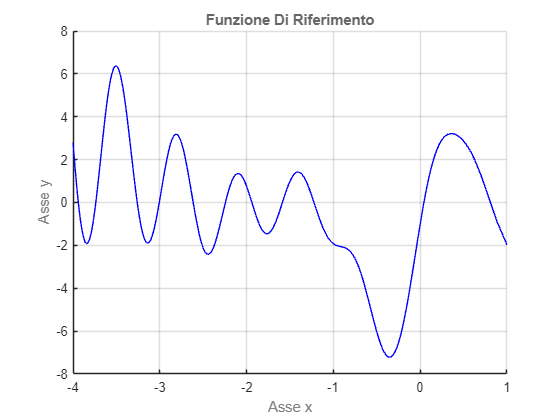

format long % formato long serve per visualizzare 15 cifre dopo la virgola.

figure(10)
warning('off')
hold on 
grid on % visualizzo la griglia
intervallo=[-4, 1]; %intervallo di funrif
fplot(funrif, intervallo, 'Color', 'b')

xlabel('Asse x', 'Color', '#808080')
ylabel('Asse y', 'Color', '#808080')
title('Funzione Di Riferimento', 'Color', '#666666')

## **Punto 2: **

#### Visualizzate il grafico della funzione di riferimento in $[a,b]$, specificando espicitamente quale intervallo avete scelto, per esempio utilizzando un tratto più spesso rispetto a quello dell'asse x (che deve essere esplicitamente visualizzato con una linea nera; usate i comandi `title` e `legend` per rendere più leggibile la figura;

Definisco il formato per la rappresentazione dell'output

format long

Il sotto intervallo di riferimento che ho preso è: [-3.25, -1.35].

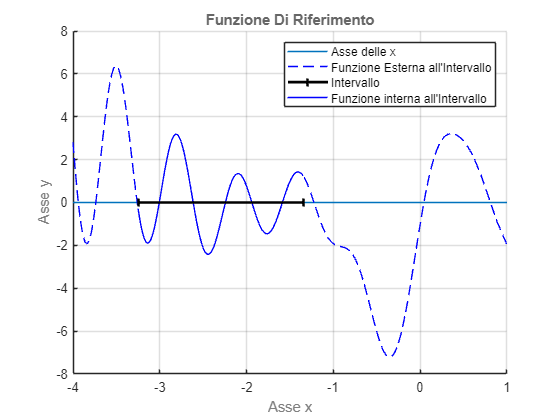

figure(20)
hold on
grid on

sottoIntervallo = [-3.25,-1.35];
plot(intervallo, [0,0])
fplot(funrif, intervallo, '--b')
line(sottoIntervallo,[0,0],'Color','k','LineWidth', 2,'marker','|')

fplot(funrif,sottoIntervallo,"b")
plot(sottoIntervallo,[0,0],'k','LineWidth',2) 

xlabel('Asse x', 'Color', '#808080')
ylabel('Asse y', 'Color', '#808080')
title('Funzione Di Riferimento', 'Color', '#666666')
legend('Asse delle x','Funzione Esterna all''Intervallo','Intervallo','Funzione interna all''Intervallo')

## **Punto 3:**

#### Usate la function Matlab `fzero` per determinare i 5 zeri della vostra funzione di riferimento in $[a,b]$, e considerate i valori calcolati da `fzero` come le soluzioni esatte; 

La funzione `fzero` opera attraverso un algoritmo combinato che integra il metodo di *bisezione*, il metodo delle *secanti* e il metodo di *interpolazione* *quadratica inversa*, assicurando una costante convergenza. 

Poiché non individua tutti gli zeri è necessario richiamare la funzione cinque volte. 

I parametri di input consistono in due elementi: il primo è il riferimento alla funzione che implementa $f$, mentre il secondo può essere un singolo valore (indicante un'approssimazione iniziale della soluzione) o un vettore (rappresentante gli estremi di un intervallo che contiene la soluzione). Nel contesto specifico, i parametri sono `funrif` ed un'approssimazione $x_0$.

z1 = fzero(funrif, -3.01)

z1 =   -3.005950480367369


z2 = fzero(funrif, -2.61)

z2 =   -2.615489821341707


z3 = fzero(funrif, -2.24)

z3 =   -2.244294490093859


z4 = fzero(funrif, -1.93)

z4 =   -1.939092361631102


z5 = fzero(funrif, -1.58)

z5 =   -1.587612107342895


Implementazione nel grafico degli zero della funzione.

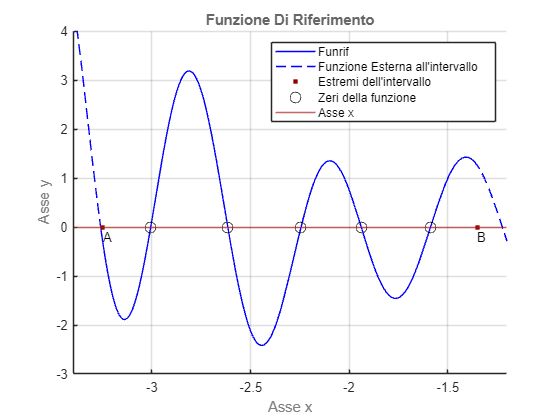

figure(30)
hold on
grid on

fplot(funrif, [-3.26, -1.34], 'Color', 'b')
fplot(funrif, intervallo, '--b')
axis([-3.4 -1.2 -3 4])
yline(0, '-', 'Color', '#B22222') 

% Estermi [a, b] dell'intervallo
plot([-3.25, -1.35], [0 0], 'sy', 'Color', '#B22222', 'MarkerFaceColor','#8B0000', 'MarkerSize',4)
text(-3.25, -0.2, 'A', 'Color', 'k')
text(-1.35, -0.2, 'B', 'Color', 'k')

% Cinque zeri
plot([z1 z2 z3 z4 z5], [0 0 0 0 0], 'O', 'Color', 'k', 'MarkerSize', 8)

xlabel('Asse x', 'Color', '#808080')
ylabel('Asse y', 'Color', '#808080')
title('Funzione Di Riferimento', 'Color', '#666666')
legend('Funrif', 'Funzione Esterna all''intervallo','Asse x', 'Estremi dell''intervallo','Zeri della funzione')

## **Punto 4:**

#### Indicate sul grafico (comando text) con un pallino rosso i 5 zeri, il primo valore minimo e l'ascissa del primo minimo (detta punto di minimo 1) entrambi con un triangolino down blu, il secondo valore minimo e l'ascissa del secondo minimo (detta punto di minimo 2) entrambi con un triangolino down verde, il primo valore massimo e l'ascissa del primo massimo (detta punto di massimo 1) entrambi con un triangolino up blu, il secondo valore massimo e l'ascissa del secondo massimo (detta punto di massimo 2) entrambi con un triangolino up verde; usate i comandi title e legend per rendere più leggibile la figura;

Sotto intervallo di riferimento `[-3.25, -1.35]`.

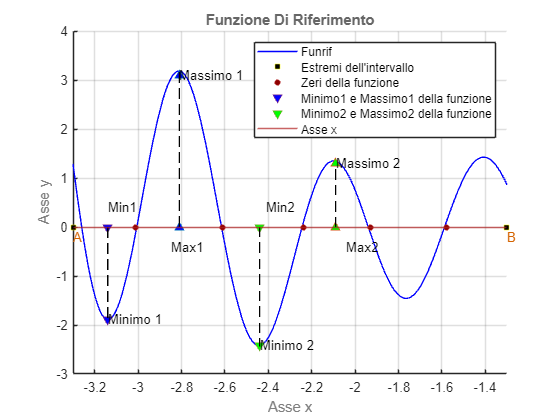

figure(40)
hold on
grid on

fplot(funrif, [-3.30 -1.30], 'Color', 'b')
axis([-3.3 -1.3 -3 4])
yline(0, '-', 'Color', '#B22222') 

% Estermi [a, b] dell'intervallo
plot([-3.30 -1.30], [0 0], 'sy', 'MarkerSize', 5, 'MarkerFaceColor', 'k')
text(-3.30, -0.2, 'A', 'Color', '#d46400')
text(-1.30, -0.2, 'B', 'Color', '#d46400')

% Cinque zeri
plot([-3.01 -2.61 -2.24 -1.93 -1.58], [0 0 0 0 0],'o', 'Color', '#B22222', 'MarkerFaceColor','#8B0000', 'MarkerSize',4)

%Evidenzio i punti di minimo e rispettive ascisse
scatter([-3.14,-3.14],[-1.88, 0], 'v', 'MarkerFaceColor', 'b')
scatter([-2.44,-2.44],[-2.41, 0], 'v', 'MarkerFaceColor', 'g')
text(-3.14, -1.88, 'Minimo 1')
text(-2.44, -2.41, 'Minimo 2')

text(-3.14, 0.4, 'Min1')
text(-2.41, 0.4, 'Min2')

% Proietto i punti di minimo
plot([-3.14 -3.14], [0 -1.88], '--', 'Color', 'k')
plot([-2.44 -2.44], [0 -2.44], '--', 'Color', 'k')

% Evidenzio i punti di massimo e rispettive ascisse
scatter([-2.81,-2.81],[3.1, 0], '^', 'MarkerFaceColor', 'b')
scatter([-2.09,-2.09],[1.3, 0], '^', 'MarkerFaceColor','g')
text(-2.81, 3.1, 'Massimo 1')
text(-2.09, 1.3, 'Massimo 2')

text(-2.85, -0.4, 'Max1')
text(-2.04, -0.4, 'Max2')

% Proietto i punti di massimo
plot([-2.81 -2.81], [0 3.18], '--', 'Color', 'k')
plot([-2.09 -2.09], [0 1.3], '--', 'Color', 'k')

xlabel('Asse x', 'Color', '#808080')
ylabel('Asse y', 'Color', '#808080')
title('Funzione Di Riferimento', 'Color', '#666666')
legend('Funrif', 'Asse x', 'Estremi dell''intervallo', 'Zeri della funzione', 'Minimo1 e Massimo1 della funzione', 'Minimo2 e Massimo2 della funzione') 

## **Punto 5:**

#### Determinate un'approssimazione dei 5 zeri, usando il metodo Newton (nostra function `Newton`) per lo zero più a sinistra (primo zero) e per il secondo zero, il metodo di bisezione (nostra function `bisezione`) per il terzo  e quarto zero e il metodo delle Secanti (nostra function `Secanti`) per il quinto zero (consiglio: usare `funtool` oppure (meglio) il toolbox simbolico (comandi `syms` , `diff `e` matlabFunction`) per determinare l'espressione della derivata della funzione di riferimento), con un valore di `delta_ass` che garantisca, in tutti e 5 i casi, che la parte intera e le prime 6 cifre frazionarie siano corrette;

Derivata della funzione `funrif`:

syms x 
funrifP = diff(funrif, x, 1) % Derivata simbolica

$$funrifP = \begin{array}{l} \frac{8\,\pi \,\cos\left(\pi \,x\right)}{\sigma_{2}}-9\,\sigma_{1}\,\sin\left(\frac{9\,x}{2}\right)\,\sigma_{3}-\frac{3\,{\sigma_{1}}^{2}\,\sigma_{3}}{5}-\frac{48\,x\,\sin\left(\pi \,x\right)}{{\sigma_{2}}^{2}}\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\frac{9\,x}{2}\right)\\ \sigma_{2}=3\,x^{2}+1\\ \sigma_{3}={\mathrm{e}}^{-\frac{3\,x}{5}} \end{array}$$

funrifP1 = matlabFunction(funrifP) % Derivata come funzione matlab

funrifP1 = function_handle with value:
    @(x)cos(x.*(9.0./2.0)).^2.*exp(x.*(-3.0./5.0)).*(-3.0./5.0)-cos(x.*(9.0./2.0)).*sin(x.*(9.0./2.0)).*exp(x.*(-3.0./5.0)).*9.0+(pi.*cos(x.*pi).*8.0)./(x.^2.*3.0+1.0)-x.*sin(x.*pi).*1.0./(x.^2.*3.0+1.0).^2.*4.8e+1


delta_ass = 1e-6; % definisco il massimo errore richiesto sul risultato

Il ***metodo di Newton*** è un algoritmo iterativo locale con una velocità di convergenza quadratica, il che significa che ad ogni passo l'errore relativo si riduce diventando il quadrato dell'errore precedente. Questo metodo è utilizzato per risolvere il problema $f(x) = 0$ ed è adatto quando:

- $f(x) = 0$ è una funziona continua e derivabile in $[a, b]$;

- $f'(x)$ è nota;

- È disponibile un'adeguata approssimazione iniziale della soluzione.

I parametri della funzione includono:

- L'handle alla funzione che definisce  $f(x)$.

- L'handle alla funzione che definisce $f'(x)$.

- Un'approssimazione iniziale della soluzione.

- L'errore massimo accettabile sul risultato.

- Il numero massimo di iterazioni consentite.

zeroNewton1 = Newton(funrif, funrifP1,z1, delta_ass, 15) 

zeroNewton1 =   -3.005950480367368


zeroNewton2 = Newton(funrif, funrifP1,z2, delta_ass, 15) 

zeroNewton2 =   -2.615489821341707


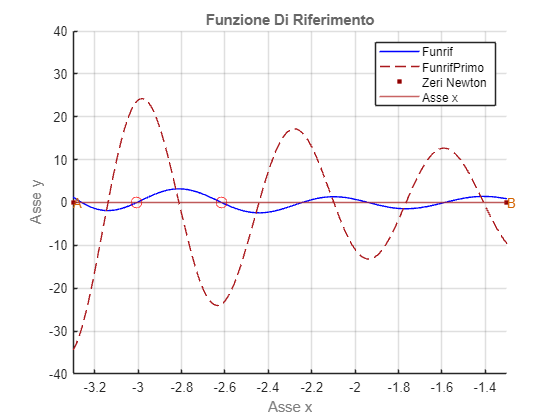

figure(55)
grid on
hold on

fplot(funrif, [-3.30 -1.30], 'Color', 'b')
fplot(funrifP, [-3.30 -1.30], '--', 'Color', '#ab191d')
axis([-3.3 -1.3 -40 40])
yline(0, '-', 'Color', '#B22222')

plot([-3.30 -1.30], [0 0], 'sy', 'Color', '#B22222', 'MarkerFaceColor','#8B0000', 'MarkerSize',4)
text(-3.30, -0.2, 'A', 'Color', '#d46400')
text(-1.30, -0.2, 'B', 'Color', '#d46400')

plot([zeroNewton1 zeroNewton2 ],[0 0],'O', 'Color', 'r','MarkerSize', 8)
xlabel('Asse x', 'Color', '#808080')
ylabel('Asse y', 'Color', '#808080')
title('Funzione Di Riferimento', 'Color', '#666666')
legend('Funrif', 'FunrifPrimo', 'Asse x', 'Zeri Newton')

Il ***metodo di Bisezione*** è un algoritmo iterativo globale che converge sempre e ha una velocità di convergenza lineare. Questo metodo si basa sull'approccio "divide et impera". È utilizzato per risolvere il problema  $f(x) = 0$ ed è adatto quando:

- $f(x)$ è una funzione continua in $[a, b]$;

- $f(x)$ cambia segno in $[a, b]$ ($f(a)f(b) < 0$).

Inoltre, è necessario conoscere la funzione $f(x)$ insieme all'intervallo  $[a, b]$.

I parametri della funzione includono:

- L'handle alla funzione che definisce $f(x)$.

- L'estremo sinistro dell'intervallo.

- L'estremo destro dell'intervallo.

- L'errore massimo richiesto sul risultato.

zeroBisezione1 = bisezione(funrif,-2.2,-2.3, delta_ass)

zeroBisezione1 =   -2.244294357299804


zeroBisezione2 = bisezione(funrif,-1.93,-1.94, delta_ass)

zeroBisezione2 =   -1.939092102050781


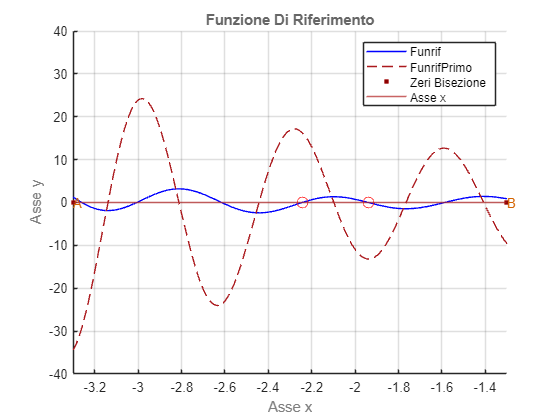

figure(56)
grid on
hold on

fplot(funrif, [-3.30 -1.30], 'Color', 'b')
fplot(funrifP, [-3.30 -1.30], '--', 'Color', '#ab191d')
axis([-3.3 -1.3 -40 40])
yline(0, '-', 'Color', '#B22222')

plot([-3.30 -1.30], [0 0], 'sy', 'Color', '#B22222', 'MarkerFaceColor','#8B0000', 'MarkerSize',4)
text(-3.30, -0.2, 'A', 'Color', '#d46400')
text(-1.30, -0.2, 'B', 'Color', '#d46400')

plot([zeroBisezione1 zeroBisezione2],[0 0],'O', 'Color', 'r','MarkerSize', 8)
xlabel('Asse x', 'Color', '#808080')
ylabel('Asse y', 'Color', '#808080')
title('Funzione Di Riferimento', 'Color', '#666666')
legend('Funrif', 'FunrifPrimo', 'Asse x', 'Zeri Bisezione')

Il metodo delle Secanti è un algoritmo iterativo locale con una velocità di convergenza superlineare. Ciò significa che ad ogni passo, l'errore relativo si riduce diventando una potenza dell'errore precedente. Questo metodo risolve il problema $f(x) = 0$ ed è adatto quando:

- $f(x)$ è una funzione continua in $[a, b]$;

- si conosce una buona approssimazione iniziale della soluzione;

I parametri della funzione includono:

- L'handle alla funzione che definisce $f(x)$.

- L'estremo sinistro dell'intervallo.

- L'estremo destro dell'intervallo.

- L'errore massimo richiesto sul risultato.

- Il numero massimo di iterazioni consentite.

zeroSecanti = Secanti(funrif,-1.57,-1.58, delta_ass, 15)

zeroSecanti =   -1.587611734699125


Adesso possiamo rappresentare graficamente la tutte le funzioni e la sua derivata.

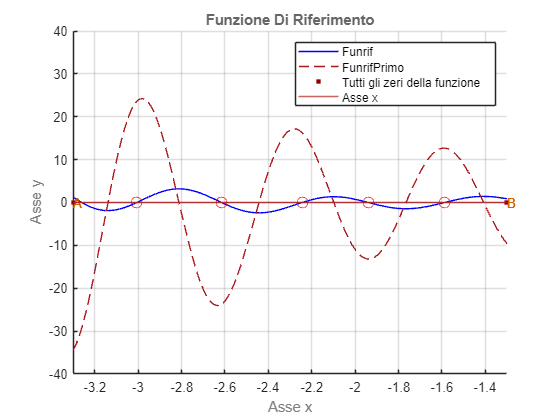

figure(50)
grid on
hold on

fplot(funrif, [-3.30 -1.30], 'Color', 'b')
fplot(funrifP, [-3.30 -1.30], '--', 'Color', '#ab191d')
axis([-3.3 -1.3 -40 40])
yline(0, '-', 'Color', '#B22222')

plot([-3.30 -1.30], [0 0], 'sy', 'Color', '#B22222', 'MarkerFaceColor','#8B0000', 'MarkerSize',4)
text(-3.30, -0.2, 'A', 'Color', '#d46400')
text(-1.30, -0.2, 'B', 'Color', '#d46400')

plot([zeroNewton1 zeroNewton2 zeroBisezione1 zeroBisezione2 zeroSecanti],[0 0 0 0 0],'O', 'Color', 'r','MarkerSize', 8)
xlabel('Asse x', 'Color', '#808080')
ylabel('Asse y', 'Color', '#808080')
title('Funzione Di Riferimento', 'Color', '#666666')
legend('Funrif', 'FunrifPrimo', 'Asse x', 'Tutti gli zeri della funzione')

## **Punto 6:**

#### Considerate sia l'errore assoluto tra l'approssimazione di Newton e la corrispondente soluzione esatta (per entrambi gli zeri calcolati con Newton), sia l'errore assoluto tra l'approssimazione della bisezione e la corrispondente soluzione esatta (per entrambi gli zeri calcolati con bisezione), sia l'errore assoluto tra l'approssimazione di Secanti e la corrispondente soluzione esatta, e verificate che siano minori dell'accuratezza richiesta (delta_ass), commentando il loro valore; calcolate anche il residuo per ognuna delle cinque approssimazioni e commentate i valori del residuo confrontandoli con quelli del corrispondente errore assoluto  e con l'accuratezza richiesta; solo guardando il grafico della funzione di riferimento, scrivere se, per ognuno dei cinque zeri, il problema appare bene o mal condizionato, spiegando qual è il significato di problema ben/mal condizionato;

Consideriamo un numero $x$  e la sua approssimazione $a$ .` L'errore assoluto` di $a$ rispetto a $x$ è definito come la differenza assoluta tra$x$ ed $a$ , ovvero $|x - a|$. *Secondo il teorema dell'errore assoluto*, se $x$ ed $a$ hanno la stessa parte intera e le stesse prime $m$ cifre della parte frazionaria, allora $E_{ass} = |x - a| < 10^{-m}$.

In questa sezione, calcoleremo l'errore assoluto tra gli zeri calcolati con la funzione *fzero *e gli zeri calcolati con i tre metodi del punto 5. Successivamente, verificheremo mediante un confronto logico se l'errore calcolato è minore dell'accuratezza richiesta.

%Calcolo dell'errore assoluto tra il primo zero calcolato con newton e il
%primo zero calcolato con fzero
err_Ass1 = abs(zeroNewton1 - z1)

err_Ass1 =      4.440892098500626e-16


if err_Ass1 <= delta_ass
    fprintf('La prima approssimazione ottenuta tramite il metodo di Newton e'' inferiore o uguale all''accuratezza richiesta.')
else
    fprintf('La prima approssimazione ottenuta tramite il metodo di Newton e'' maggiore dell''accuratezza richiesta.')
end

La prima approssimazione ottenuta tramite il metodo di Newton e' inferiore o uguale all'accuratezza richiesta.

%Calcolo dell'errore assoluto tra il secondo zero calcolato con newton e il
%secondo zero calcolato con fzero
err_Ass2 = abs(zeroNewton2 - z2)

err_Ass2 =      0


if err_Ass2 <= delta_ass
    fprintf('La seconda approssimazione ottenuta tramite il metodo di Newton e'' inferiore o uguale all''accuratezza richiesta.')
else
    fprintf('La seconda approssimazione ottenuta tramite il metodo di Newton e'' maggiore dell''accuratezza richiesta.')
end

La seconda approssimazione ottenuta tramite il metodo di Newton e' inferiore o uguale all'accuratezza richiesta.

%Calcolo dell'errore assoluto tra il primo zero calcolato con il metodo di bisezione e il
%terzo zero calcolato con fzero
err_Ass3 = abs(zeroBisezione1 - z3)

err_Ass3 =      1.327940548634388e-07


if err_Ass3 <= delta_ass
    fprintf('La prima approssimazione ottenuta tramite il metodo della Bisezione e'' inferiore o uguale all''accuratezza richiesta.')
else
    fprintf('La prima approssimazione ottenuta tramite il metodo della Bisezione e'' maggiore dell''accuratezza richiesta.')
end

La prima approssimazione ottenuta tramite il metodo della Bisezione e' inferiore o uguale all'accuratezza richiesta.

%Calcolo dell'errore assoluto tra il secondo zero calcolato con il metodo di bisezione e il
%quarto zero calcolato con fzero
err_Ass4 = abs(zeroBisezione2 - z4)

err_Ass4 =      2.595803205718283e-07


if err_Ass4 <= delta_ass
    fprintf('La seconda approssimazione ottenuta tramite il metodo della Bisezione è inferiore o uguale all''accuratezza richiesta.')
else
    fprintf('La seconda approssimazione ottenuta tramite il metodo della Bisezione e'' maggiore dell''accuratezza richiesta.')
end

La seconda approssimazione ottenuta tramite il metodo della Bisezione è inferiore o uguale all'accuratezza richiesta.

%Calcolo dell'errore assoluto tra il primo zero calcolato con fzero e con
%il metodo delle Secanti
err_Ass5 = abs(zeroSecanti - z5)

err_Ass5 =      3.726437696194296e-07


if err_Ass5 <= delta_ass
    fprintf('Approssimazione ottenuta tramite il metodo delle Secanti è inferiore o uguale all''accuratezza richiesta.')
else
    fprintf('Approssimazione ottenuta tramite il metodo delle Secanti e'' maggiore dell''accuratezza richiesta.')
end

Approssimazione ottenuta tramite il metodo delle Secanti è inferiore o uguale all'accuratezza richiesta.

Il *residuo* verifica l'accuratezza dell'approssimazione, possiamo ricavarlo facendo il valore assoluto della funzione calcolata nel punto in questione.

resNewton1 = abs(funrif(zeroNewton1))

resNewton1 =      1.754152378907747e-14


L'ordine di grandezza del residuo calcolato è maggiore dell'accuratezza richiesta ($10^{-6}$), anche se differiscono per una sola cifra, potrebbe ancora essere accettabile e considerabile ben condizionato.

resNewton2 = abs(funrif(zeroNewton2))

resNewton2 =      3.108624468950438e-15


L'ordine di grandezza del residuo calcolato è maggiore dell'accuratezza richiesta ($10^{-6}$), anche se differiscono per una sola cifra, potrebbe ancora essere accettabile e considerabile ben condizionato.

resBisezione1 = abs(funrif(zeroBisezione1))

resBisezione1 =      2.164986297348293e-06


il problema è quindi ben condizionato poichè l'ordine di grandezza del residuo calcolato è uguale all'accuratezza richiesta ($10^{-6}$).

resBisezione2 = abs(funrif(zeroBisezione2))

resBisezione2 =      3.423404324687240e-06


il problema è quindi ben condizionato poichè l'ordine di grandezza del residuo calcolato è uguale all'accuratezza richiesta ($10^{-6}$).

resSecante = abs(funrif(zeroSecanti))

resSecante =      4.721445157063187e-06


il problema è quindi ben condizionato poichè l'ordine di grandezza del residuo calcolato è uguale all'accuratezza richiesta ($10^{-6}$).

In questo caso utilizziamo l'`indice di condizionamento `per poterci calcolare il `condizionamento `.Esso viene calcolato tramite la formula $k_f(r) = |f'(r)|^{-1}$, che si può trasformare in $\frac{1}{|f'(r)|^{1}}$.

kfNewton1 =  1 / abs(funrifP1(zeroNewton1))

kfNewton1 =    0.042414524501183


kfNewton2 =  1 / abs(funrifP1(zeroNewton2))

kfNewton2 =    0.042219923568091


kfBisezione1 = 1 / abs(funrifP1(zeroBisezione1))

kfBisezione1 =    0.061337146220342


kfBisezione2 = 1 / abs(funrifP1(zeroBisezione2))

kfBisezione2 =    0.075825199453413


kfSecanti = 1 / abs(funrifP1(zeroSecanti))

kfSecanti =    0.078925789502143


Adesso passiamo al grafico della funzione:

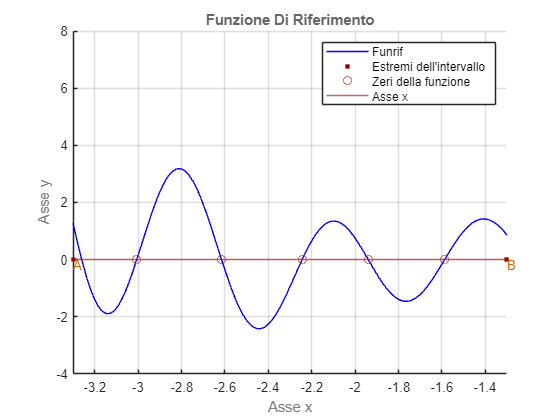

figure(60)
grid on
hold on

fplot(funrif, [-3.30 -1.30], 'Color', 'b')
axis([-3.30 -1.3 -4 8])
yline(0, '-', 'Color', '#B22222')

plot([-3.30 -1.30], [0 0], 'sy', 'Color', '#B22222', 'MarkerFaceColor','#8B0000', 'MarkerSize',4)
text(-3.30, -0.2, 'A', 'Color', '#d46400')
text(-1.30, -0.2, 'B', 'Color', '#d46400')

plot([zeroNewton1 zeroNewton2 zeroBisezione1 zeroBisezione2 zeroSecanti], [0 0 0 0 0],'O', 'Color', '#B22222')
xlabel('Asse x', 'Color', '#808080')
ylabel('Asse y', 'Color', '#808080')
title('Funzione Di Riferimento', 'Color', '#666666')
legend('Funrif', 'Asse x', 'Estremi dell''intervallo', 'Zeri della funzione')

## **Punto 7:**

#### Osservando il grafico della vostra funzione di riferimento nell'intervallo e della bisettrice del primo quadrante, stabilite se ci sono punti fissi e determinate il loro numero; poi, senza usare la function PFisso (suggerimento: trasformate il problema di punto fisso in un problema equivalente di risoluzione di una equazione e usate opportunamente fzero), calcolate una approssimazione dei due punti fissi più vicini all'estremo sinistro dell'intervallo, cioè più vicini ad , visualizzateli sul grafico con  un quadrato nero e determinate i loro residui; dite se il metodo del punto fisso convergerebbe a tali punti fissi. Solo per i punti fissi per cui la teoria assicuri la convergenza (suggerimento: calcolate e visualizzate la derivata della funzione di riferimento nei due punti fissi considerati), calcolate tali punti fissi anche con la nostra function PFisso; commentate i risultati; usate i comandi title e legend per rendere più leggibile la figura;

Il `punto fisso `della funzione $g$, indicato con $p$, è tale che quando lo sostituisci in g, ottieni  $g(p) = p$.

Dal punto di vista geometrico, se consideriamo il punto nel piano con coordinate $(p, g(p))$, questo punto ha la caratteristica speciale di avere la stessa ascissa e ordinata. Di conseguenza, tale punto deve giacere sulla retta bisettrice dei quadranti primo e terzo.

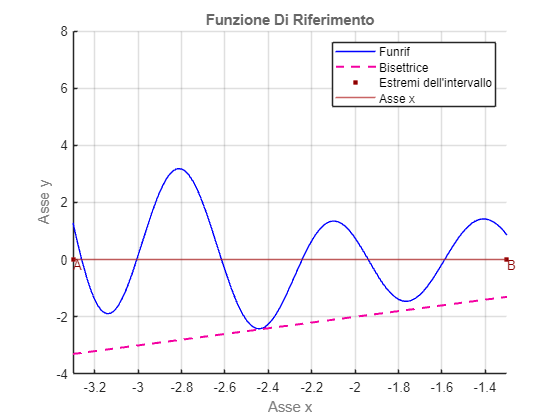

figure(70)
hold on
grid on

fplot(funrif, [-3.30 -1.30], 'Color', 'b')
fplot(@(x) x, [-3.30 -1.30],'--', 'Color', '#f400a1', 'LineWidth', 1.5)
axis([-3.30 -1.30 -4 8])
yline(0, '-', 'Color', '#B22222')

plot([-3.30 -1.30], [0 0], 'sy', 'Color', '#B22222', 'MarkerFaceColor','#8B0000', 'MarkerSize',4)
text(-3.30, -0.2, 'A', 'Color', '#8B0000') 
text(-1.30, -0.2, 'B', 'Color', '#8B0000')

xlabel('Asse x', 'Color', '#808080')
ylabel('Asse y', 'Color', '#808080')
title('Funzione Di Riferimento', 'Color', '#666666')
legend('Funrif', 'Bisettrice', 'Asse x', 'Estremi dell''intervallo','Punto fisso')

Dato che non c'è il punto fisso non c'è convergenza. 

In questo caso la bisettrice non tocca il nostro sotto intervallo.

Se ad esempio prendessimo un altro intervallo come riferimento [ -2 , 0.5 ], notiamo come nel punto [-1.122 -1.122] e nel punti [0.045, 0.045 ] la bisettrice incontra la nostra funzione di riferimento.

figure(75)
hold on
grid on

h = @(x) -x + funrif(x);
pfisso1 = fzero(h,-1.122)

pfisso1 =   -1.125529169707018


pfisso2 = fzero(h,0.045)

pfisso2 =    0.044556062555194


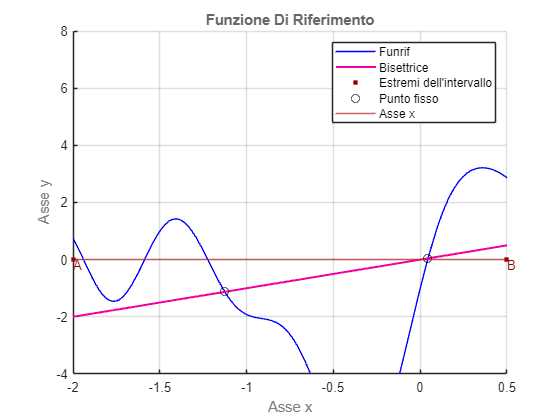


fplot(funrif, [-2 0.5], 'Color', 'b')
fplot(@(x) x, [-2 0.5], 'Color', '#f400a1', 'LineWidth', 1.5)
axis([-2 0.5 -4 8])
yline(0, '-', 'Color', '#B22222')

plot([-2 0.5], [0 0], 'sy', 'Color', '#B22222', 'MarkerFaceColor','#8B0000', 'MarkerSize',4)
text(-2, -0.2, 'A', 'Color', '#8B0000') 
text(0.5, -0.2, 'B', 'Color', '#8B0000')

plot(pfisso1,pfisso1, 'O', 'Color', 'k') 
plot(pfisso2,pfisso2, 'O', 'Color', 'k') 

xlabel('Asse x', 'Color', '#808080')
ylabel('Asse y', 'Color', '#808080')
title('Funzione Di Riferimento', 'Color', '#666666')
legend('Funrif', 'Bisettrice', 'Asse x', 'Estremi dell''intervallo','Punto fisso')

%Convergenza punto fisso intervallo [ -2 , 0.5 ]
abs(funrifP1(-1.122)) < 1

ans = logical
   0


abs(funrifP1(0.045)) < 1

ans = logical
   0


## **Punto 8:**

#### Usate la function Matlab fminbnd per determinare i due punti di minimo e i due punti di massimo della vostra funzione di riferimento in $[a,b]$, con quattro chiamate del tipo: fminbnd(fun,sinistro,destro,optimset('TolX',1e-10)), e considerate i valori calcolati da fminbnd come le soluzioni esatte (cioè come valori esatti dei due punti di minimo e dei due punti di massimo). Visualizzate sul grafico sia i punti di minimo e massimo, sia i valori minimi e massimi ivi assunti dalla funzione di riferimento;

Per ottenere i punti di minimo, mi affido alla funzione fminbnd. Una volta individuato il minimo, calcolo il valore di funrif in quel punto.

minp1 = fminbnd(funrif, -3.1425, -3.1415, optimset('TolX', 1e-10)) % Serve per ricavare il primo punto di minimo

minp1 =   -3.141500060117978


min1 = funrif(minp1) % Serve per calcolare il primo minimo

min1 =   -1.887596422675873


minp2 = fminbnd(funrif, -2.46, -2.42, optimset('TolX', 1e-10)) % Serve per ricavare il secondo punto di minimo

minp2 =   -2.442970842690765


min2 = funrif(minp2) % Serve per ricavare il secondo minimo

min2 =   -2.416388865659826


È anche fattibile utilizzare la medesima funzione per individuare i punti di massimo; per fare ciò, basta invertire la funzione e determinare i punti di minimo della funzione invertita.

maxp1 = fminbnd(@(x) -funrif(x), -2.81, -2.79, optimset('TolX', 1e-10)) % Serve per ricavare il primo punto di massimo

maxp1 =   -2.809999926319706


max1 = funrif(maxp1) % serve per ricavare il primo massimo

max1 =    3.182404583034406


maxp2 = fminbnd(@(x) -funrif(x), -2.11, -2.08, optimset('TolX', 1e-10)) % Serve per ricavare il secondo punto di massimo

maxp2 =   -2.098460411226668


max2 = funrif(maxp2) % Serve per ricavare il secondo massimo

max2 =    1.349615290955827


Verifichiamo i punti trovati graficamente:

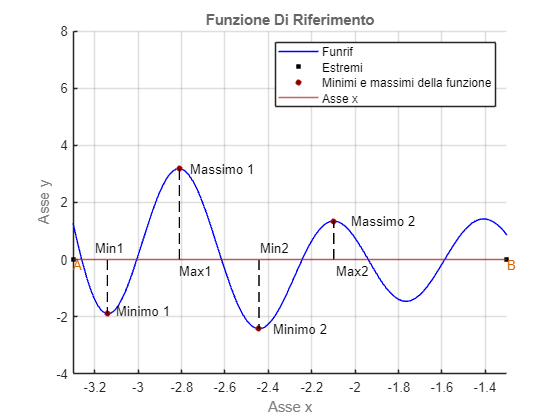

figure(80)
hold on
grid on

fplot(funrif, [-3.30 -1.30], 'Color', 'b')
axis([-3.3 -1.3 -4 8])
yline(0, '-', 'Color', '#B22222')

plot([-3.30 -1.30], [0 0], 'sy', 'Color', 'k', 'MarkerFaceColor','k', 'MarkerSize',4)
text(-3.30, -0.2, 'A', 'Color', '#d46400')
text(-1.30, -0.2, 'B', 'Color', '#d46400')

% Evidenzio i minimi
plot([minp1 minp2], [min1 min2], 'or','Color', '#B22222', 'MarkerFaceColor','#8B0000', 'MarkerSize',4)
text(-3.1, -1.8, 'Minimo 1')
text(-2.38, -2.41, 'Minimo 2')
text(-3.2, 0.4, 'Min1')
text(-2.44, 0.4, 'Min2')

% Proietto i punti di minimo
plot([minp1 minp1], [0 min1], '--', 'Color', 'k')
plot([minp2 minp2], [0 min2], '--', 'Color', 'k')

% Evidenzio i massimi
plot([maxp1 maxp2], [max1 max2], 'or', 'Color', '#B22222', 'MarkerFaceColor','#8B0000', 'MarkerSize',4)
text(-2.76, 3.18, 'Massimo 1')
text(-2.02, 1.34, 'Massimo 2')
text(-2.81, -0.4, 'Max1')
text(-2.09, -0.4, 'Max2')

% Proietto i punti di massimo
plot([maxp1 maxp1], [0 max1], '--', 'Color', 'k')
plot([maxp2 maxp2], [0 max2], '--', 'Color', 'k')

xlabel('Asse x', 'Color', '#808080')
ylabel('Asse y', 'Color', '#808080')
title('Funzione Di Riferimento', 'Color', '#666666')
legend('Funrif', 'Asse x', 'Estremi' , 'Minimi e massimi della funzione')

## **Punto 9:**

#### Verificate che i due punti di minimo e i due punti di massimo sono zeri della derivata della vostra funzione di riferimento (consiglio: usare funtool o (meglio)  il toolbox simbolico (comandi syms , diff e matlabFunction) per determinare l'espressione della derivata della funzione di riferimento), visualizzando nella stessa figura sia il grafico della funzione (in blu) sia il grafico della sua derivata (in rosso) [può essere utile usare anche la scalatura verticale della finestra grafica data dal comando ylim([ymin, ymax]) ], e usando la fzero per calcolare tutti gli zeri della derivata nell'intervallo ; commentate i risultati ottenuti; usate i comandi title e legend per rendere più leggibile la figura;

Calcoliamo gli zeri della derivata prima:

pStazionario1 = fzero(funrifP1, -3.1)

pStazionario1 =   -3.139048880100331


pStazionario2 = fzero(funrifP1, -2.8)

pStazionario2 =   -2.811746636292523


pStazionario3 = fzero(funrifP1, -2.4)

pStazionario3 =   -2.442970849600892


pStazionario4 = fzero(funrifP1, -2)

pStazionario4 =   -2.098460411383956


Verifico i gli zeri della derivata

abs(min1 - pStazionario1) < delta_ass, abs(min2 - pStazionario2) < delta_ass, abs(max1 - pStazionario3) < delta_ass, abs(max2 - pStazionario4) < delta_ass 

ans = logical
   0


ans = logical
   0


ans = logical
   0


ans = logical
   0


Come si può osservare, i risultati differiscono dai punti di minimo e massimo solo per le cifre frazionarie finali, ma ciò è principalmente dovuto dall'accuratezza della funzione. Possiamo quindi concludere che i punti siano praticamente coincidenti.

Rappresentazione grafica:

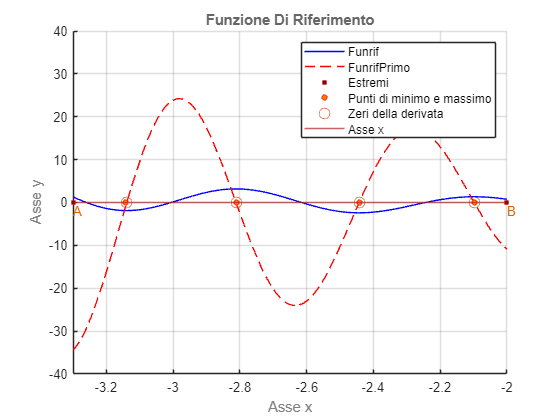

figure(90)
hold on
grid on

fplot(funrif, [-3.30 -2], 'Color', 'b')
fplot(funrifP, [-3.30 -2], '--', 'Color', '#ff0000')
axis([-3.30 -2 -40 40])
yline(0, '-', 'Color', '#B22222')

plot([-3.30 -2], [0 0], 'sy', 'Color', '#B22222', 'MarkerFaceColor','#8B0000', 'MarkerSize',4)
text(-3.30, -2, 'A', 'Color', '#d46400')
text(-2, -2, 'B', 'Color', '#d46400')
plot([minp1 minp2 maxp1 maxp2], [0 0 0 0], 'or', 'MarkerFaceColor', '#ff8001', 'MarkerSize', 4)
plot([pStazionario1 pStazionario2 pStazionario3 pStazionario4], [0 0 0 0], 'o', 'Color', '#D95319', 'MarkerSize', 8)

xlabel('Asse x', 'Color', '#808080')
ylabel('Asse y', 'Color', '#808080')
title('Funzione Di Riferimento', 'Color', '#666666')
legend('Funrif', 'FunrifPrimo', 'Asse x', 'Estremi ', 'Punti di minimo e massimo', 'Zeri della derivata')

## **Punto 10:**

#### Determinate un'approssimazione dei due punti di minimo e dei due punti di massimo, usando, rispettivamente, due volte il metodo di Fibonacci search (nostra function fminfibo) per i due minimi, e il metodo di Golden search (nostra function fmingolden) per i due massimi, con un valore di delta_ass che garantisca che la parte intera e le prime 3 cifre frazionarie siano corrette;

Definisco il massimo errore richiesto sul risultato

deltaAss = 1e-3;

#### Il ***metodo di ricerca di Fibonacci*** (***Fibonacci search***) 

Questo metodo è utilizzabile solo se si sceglie un intervallo che risulta *unimodale*, ovvero dove esiste un unico numero $r$ in $[a, b]$ tale che $f$ è decrescente in $[a, r]$ e crescente in $[r, b]$.

fiboMin1 = fminfibo(funrif,-3.14 ,-3.15 ,deltaAss)

fiboMin1 =   -3.142000000000000


fiboMin2 = fminfibo(funrif,-2.44 ,-2.45 ,deltaAss)

fiboMin2 =   -2.442000000000000


#### Il metodo di ricerca Aurea (*golden search*)

Analogamente a Fibonacci gli argomenti sono gli stessi:

goldenMax1=fmingolden(@(x)-funrif(x),-2.81 ,-2.82 , deltaAss)

goldenMax1 =   -2.811909830056250


goldenMax2=fmingolden(@(x) -funrif(x),-2.10 ,-2.11 , deltaAss)

goldenMax2 =   -2.100450849718747


Verifichiamo i punti trovati graficamente:

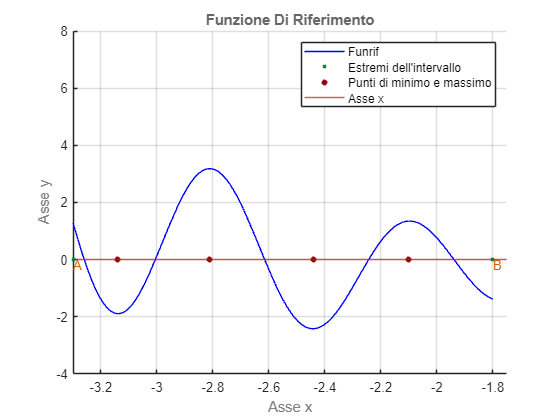

figure(100)
hold on
grid on

fplot(funrif, [-3.30 -1.80], 'Color','b')
axis([-3.30 -1.75 -4 8])
yline(0, '-', 'Color', '#B22222')

plot([-3.30 -1.80], [0 0], 'sy', 'Color', '#008f39', 'MarkerFaceColor','#008f39', 'MarkerSize',3)
text(-3.30, -0.2, 'A', 'Color', '#d46400')
text(-1.80, -0.2, 'B', 'Color', '#d46400')

plot([fiboMin1 fiboMin2 goldenMax1 goldenMax2], [0 0 0 0], 'O', 'Color', '#B22222', 'MarkerFaceColor','#8B0000', 'MarkerSize',4)

xlabel('Asse x', 'Color', '#808080')
ylabel('Asse y', 'Color', '#808080')
title('Funzione Di Riferimento', 'Color', '#666666')
legend('Funrif', 'Asse x', 'Estremi dell''intervallo', 'Punti di minimo e massimo')

## **Punto 11:**

#### Considerate l'errore assoluto tra le due approssimazioni ottenute dalle due chiamate alla Golden search e le due corrispondenti soluzioni esatte e poi l'errore assoluto tra le due approssimazioni ottenute dalle due chiamate alla Fibonacci search e le due corrispondenti soluzioni esatte, e verificate che siano in tutti e quattro i casi minori dell'accuratezza richiesta (delta_ass), commentando i risultati.

Calcolo degli errori assoluti tramite deltaAss associato ad accuratezza 1e-3:

errAssGoldSh1 = abs(goldenMax1 - maxp1)

errAssGoldSh1 =    0.001909903736544


if errAssGoldSh1 < deltaAss
    fprintf('L''errore assoluto tra goldenMax1 e maxp1 e'' minore dell''accuratezza.')
else
    fprintf('L''errore assoluto tra goldenMax1 e maxp1 e'' maggiore o uguale dell''accuratezza.''')
end

L'errore assoluto tra goldenMax1 e maxp1 e' maggiore o uguale dell'accuratezza.'

errAssGoldSh2 = abs(goldenMax2 - maxp2)

errAssGoldSh2 =    0.001990438492080


if errAssGoldSh2 < deltaAss
    fprintf('L''errore assoluto tra goldenMax2 e maxp2 e'' minore dell''accuratezza.')
else
    fprintf('L''errore assoluto tra goldenMax2 e maxp2 e'' maggiore o uguale dell''accuratezza.')
end

L'errore assoluto tra goldenMax2 e maxp2 e' maggiore o uguale dell'accuratezza.

erraAssFib1 = abs(fiboMin1 -minp1)

erraAssFib1 =      4.999398820224599e-04


if erraAssFib1 < deltaAss
    fprintf('L''errore assoluto tra fiboMin1 e minp1 e'' minore dell''accuratezza.')
else
    fprintf('L''errore assoluto tra fiboMin1 e minp1 e'' maggiore o uguale dell''accuratezza.')
end

L'errore assoluto tra fiboMin1 e minp1 e' minore dell'accuratezza.

erraAssFib2 = abs(fiboMin2 -minp2)

erraAssFib2 =      9.708426907644174e-04


if erraAssFib2 < deltaAss
    fprintf('L''errore assoluto tra fiboMin2 e minp2 e'' minore dell''accuratezza.')
else
    fprintf('L''errore assoluto tra fiboMin2 e minp2 e'' maggiore o uguale dell''accuratezza.')
end

L'errore assoluto tra fiboMin2 e minp2 e' minore dell'accuratezza.

In questo caso i primi due casi del Golden search risultano maggiori dell'accuratezza mentre gli ultimi due ovvero quelli del Fibonacci search risultano minori dell'accuratezza.